# Figure S3: remove layer 4 and see red region

clear;
clc;
addpath('../funcs');
addpath('../reduced_system');
filepath = '../../paper/figureS3/';
load ../../data/reducedL4_0_0.5_0_0.05_0.02_ratio_0_steps_200.mat;

Delta_e_start = 0; % cannot equal to 0
Delta_e_end = 0.5; % can equal to 0.5

Delta_i_start = 0; % cannot equal to 0
Delta_i_end = 0.05; % can equal to 0.05
steps = size(envSheet,1);

Iattn = 0.02;

n = 1:steps;
Delta_e = Delta_e_start+ n*(Delta_e_end/steps);
Delta_i = Delta_i_start + n*(Delta_i_end/steps);
sz = 1; % 5 for fig3
markSZ = 50;

## rule out

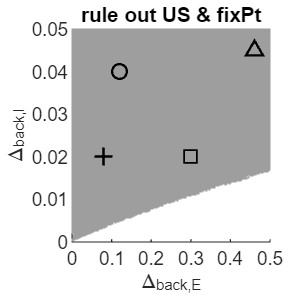

% load ../../data/reducedL4_0_0.5_0_0.05_0.02_ratio_64_steps_60.mat;

ruleOut = zeros(steps,steps);
maxPks = 12; % 12 is enough
minPks = 1;

for i = 1:steps
    for j = 1:steps
        cond4 = squeeze(psdPeaksSheet(i,j,:,5)); cond5 = squeeze(psdPeaksSheet(i,j,:,6));
        tmp = max([cond4; cond5]);
        if tmp<=maxPks && tmp>=minPks 
            ruleOut(i,j) = 1;
        end
    end
end

ruleOut = ruleOut == 1;

figure();
for i = 1:steps
    x = Delta_e(ruleOut(steps+1-i,:));
    y = Delta_i(i)*ones(length(x),1);
    s1 = scatter(x,y,sz,'s','filled',"MarkerFaceColor","#9E9E9E"); % green
    hold on;
end
scatter(0.12, 0.04, 40,"o",'LineWidth',1,'MarkerEdgeColor','k');
scatter(0.08, 0.02, 60,"+",'LineWidth',1,'MarkerEdgeColor','k');
scatter(0.3, 0.02, 50,"square",'LineWidth',1,'MarkerEdgeColor','k');
scatter(0.46, 0.045, 40,"^",'LineWidth',1,'MarkerEdgeColor','k');

hold off;
axis([0 0.5 0 0.05]);
xlabel("\Delta_{back,E}");
ylabel("\Delta_{back,I}");
xticks([0 0.1 0.2 0.3 0.4 0.5]);
yticks([0 0.01 0.02 0.03 0.04 0.05]);
title("rule out US & fixPt");

x0 = 0; y0 = 0; width = 4.5; height = 4.5;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);

## only attention, green

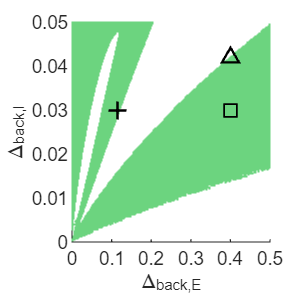

pop = 1;
WTA = zeros(steps,steps);

for i = 1:steps
    for j = 1:steps
        cond0 = envSheet(i,j,pop,1); cond1 = envSheet(i,j,pop,2); cond2 = envSheet(i,j,pop,3);
        cond3 = envSheet(i,j,pop,4); cond4 = envSheet(i,j,pop,5); cond5 = envSheet(i,j,pop,6);
        % if cond4>cond5
        if cond4 - cond5 >-7e-07 %
            WTA(i,j) = 1;
        end
    end
end
envSheet_onlyAttn = envSheet;
WTA = WTA == 1;
WTA = and(WTA,ruleOut);

figure();
for i = 1:steps
    x = Delta_e(WTA(steps+1-i,:));
    y = Delta_i(i)*ones(length(x),1);
    s1 = scatter(x,y,sz,'s','filled',"MarkerFaceColor","#6cd47f"); % green
    hold on;
end

% scatter(0.12, 0.04, 40,"o",'LineWidth',1,'MarkerEdgeColor','k');
scatter(0.115, 0.03, 60,"+",'LineWidth',1,'MarkerEdgeColor','k');
scatter(0.4, 0.03, 50,"square",'LineWidth',1,'MarkerEdgeColor','k');
scatter(0.4, 0.042, 40,"^",'LineWidth',1,'MarkerEdgeColor','k');

hold off;
axis([0 0.5 0 0.05]);
xlabel("\Delta_{back,E}");
ylabel("\Delta_{back,I}");
xticks([0 0.1 0.2 0.3 0.4 0.5]);
yticks([0 0.01 0.02 0.03 0.04 0.05]);

x0 = 0; y0 = 0; width = 4.5; height = 4.5;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
filename = append(filepath,'scatter_green');
print(filename, '-dpng', '-r600');
print(filename, '-dsvg', '-r600');

## add sensory, blue

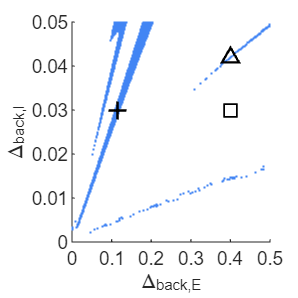

load ../../data/reducedL4_0_0.5_0_0.05_0.02_ratio_3_steps_200.mat;
pop = 1;

antiWTA_env = zeros(steps,steps);
useSheet = envSheet;
for i = 1:steps
    for j = 1:steps
        cond0 = useSheet(i,j,pop,1); cond1 = useSheet(i,j,pop,2); cond2 = useSheet(i,j,pop,3);
        cond3 = useSheet(i,j,pop,4); cond4 = useSheet(i,j,pop,5); cond5 = useSheet(i,j,pop,6);
        noOsci = osciSheet(i,j,5,5);
        if cond4<cond5 && noOsci==0
            antiWTA_env(i,j) = 1;
        end
    end
end

antiWTA = zeros(steps,steps);
useSheet = meanSheet;
for i = 1:steps
    for j = 1:steps
        cond0 = useSheet(i,j,pop,1); cond1 = useSheet(i,j,pop,2); cond2 = useSheet(i,j,pop,3);
        cond3 = useSheet(i,j,pop,4); cond4 = useSheet(i,j,pop,5); cond5 = useSheet(i,j,pop,6);
        if cond4<cond5
            antiWTA(i,j) = 1;
        end
    end
end

antiWTA = antiWTA == 1;
antiWTA = and(antiWTA,WTA);
antiWTA = and(antiWTA_env, antiWTA);

% antiWTA = zeros(steps,steps);
% useSheet = envSheet;
% for i = 1:steps
%     for j = 1:steps
%         pop1cond0 = useSheet(i,j,1,1); pop1cond1 = useSheet(i,j,1,2); pop1cond2 = useSheet(i,j,1,3);
%         pop1cond3 = useSheet(i,j,1,4); pop1cond4 = useSheet(i,j,1,5); pop1cond5 = useSheet(i,j,1,6);
% 
%         pop5cond0 = useSheet(i,j,5,1); pop5cond1 = useSheet(i,j,5,2); pop5cond2 = useSheet(i,j,5,3);
%         pop5cond3 = useSheet(i,j,5,4); pop5cond4 = useSheet(i,j,5,5); pop5cond5 = useSheet(i,j,5,6);
% 
%         noOsci = osciSheet(i,j,5,5);
%         if pop1cond4<pop1cond5 % && noOsci==0 %%&& pop5cond1<pop5cond3%%~(pop5cond1>pop5cond3 && pop5cond4>pop5cond3 && pop5cond3>pop5cond5 && pop5cond3>pop5cond2)
%             antiWTA(i,j) = 1;
%         end
%     end
% end

% antiWTA = antiWTA == 1;
% antiWTA = and(antiWTA,WTA);

figure();
for i = 1:steps
    x = Delta_e(antiWTA(steps+1-i,:));
    y = Delta_i(i)*ones(length(x),1);
    s1 = scatter(x,y,sz,'s','filled',"MarkerFaceColor","#4285F4"); % blue
    hold on;
end

% scatter(0.12, 0.04, 40,"o",'LineWidth',1,'MarkerEdgeColor','k');
scatter(0.115, 0.03, 60,"+",'LineWidth',1,'MarkerEdgeColor','k');
scatter(0.4, 0.03, 50,"square",'LineWidth',1,'MarkerEdgeColor','k');
scatter(0.4, 0.042, 40,"^",'LineWidth',1,'MarkerEdgeColor','k');

hold off;
axis([0 0.5 0 0.05]);
xlabel("\Delta_{back,E}");
ylabel("\Delta_{back,I}");
xticks([0 0.1 0.2 0.3 0.4 0.5]);
yticks([0 0.01 0.02 0.03 0.04 0.05]);
% title("S&A: anti-WTA");

x0 = 0; y0 = 0; width = 4.5; height = 4.5;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);

filename = append(filepath,'scatter_blue');
print(filename, '-dpng', '-r600');
print(filename, '-dsvg', '-r600');

## Sensory + Attention, ordered pattern, yellow

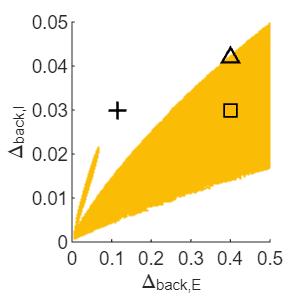

pop = 5;
order = zeros(steps,steps);
useSheet = envSheet;
for i = 1:steps
    for j = 1:steps
        cond0 = useSheet(i,j,pop,1); cond1 = useSheet(i,j,pop,2); cond2 = useSheet(i,j,pop,3);
        cond3 = useSheet(i,j,pop,4); cond4 = useSheet(i,j,pop,5); cond5 = useSheet(i,j,pop,6);
        
        cond4_pks = squeeze(psdPeaksSheet(i,j,pop,5)); cond5_pks = squeeze(psdPeaksSheet(i,j,pop,6));
        tmp = max([cond4_pks; cond5_pks]);
        betaP = betaPSheet(i,j,pop,5);
        pop1cond4 = useSheet(i,j,1,5); pop1cond5 = useSheet(i,j,1,6);
        %% if cond1>cond4 && cond1>cond3 && cond4>cond3 && cond3>cond2 && cond3>cond5 && tmp==1 % && betaP<0.001 && pop1cond4-pop1cond5>0.00001
        if cond1>cond3 && cond4>cond3 && cond3>cond2 && cond3>cond5 && tmp>=1 && tmp<=4 % && cond5>cond2
            order(i,j) = 1;
        end
    end
end

order = order == 1;
% order = and(order,WTA);

figure();
for i = 1:steps
    x = Delta_e(order(steps+1-i,:));
    y = Delta_i(i)*ones(length(x),1);
    s1 = scatter(x,y,sz,'s','filled',"MarkerFaceColor","#FBBC05"); % yellow
    hold on;
end

% scatter(0.12, 0.04, 40,"o",'LineWidth',1,'MarkerEdgeColor','k');
scatter(0.115, 0.03, 60,"+",'LineWidth',1,'MarkerEdgeColor','k');
scatter(0.4, 0.03, 50,"square",'LineWidth',1,'MarkerEdgeColor','k');
scatter(0.4, 0.042, 40,"^",'LineWidth',1,'MarkerEdgeColor','k');

hold off;
axis([0 0.5 0 0.05]);
xlabel("\Delta_{back,E}");
ylabel("\Delta_{back,I}");
xticks([0 0.1 0.2 0.3 0.4 0.5]);
yticks([0 0.01 0.02 0.03 0.04 0.05]);
% title("S&A: ordered pattern");

x0 = 0; y0 = 0; width = 4.5; height = 4.5;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
filename = append(filepath,'scatter_yellow');
print(filename, '-dpng', '-r600');
print(filename, '-dsvg', '-r600');

## Intersection, red

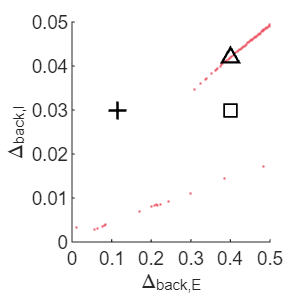

order = and(order,antiWTA);

figure();
for i = 1:steps
    x = Delta_e(order(steps+1-i,:));
    y = Delta_i(i)*ones(length(x),1);
    s1 = scatter(x,y,sz,'s','filled',"MarkerFaceColor","#ED5564"); % red
    hold on;
end

% scatter(0.12, 0.04, 40,"o",'LineWidth',1,'MarkerEdgeColor','k');
scatter(0.115, 0.03, 60,"+",'LineWidth',1,'MarkerEdgeColor','k');
scatter(0.4, 0.03, 50,"square",'LineWidth',1,'MarkerEdgeColor','k');
scatter(0.4, 0.042, 40,"^",'LineWidth',1,'MarkerEdgeColor','k');

hold off;
axis([0 0.5 0 0.05]);
xlabel("\Delta_{back,E}");
ylabel("\Delta_{back,I}");
xticks([0 0.1 0.2 0.3 0.4 0.5]);
yticks([0 0.01 0.02 0.03 0.04 0.05]);
% title("S&A: anti-WTA & ordered");

x0 = 0; y0 = 0; width = 4.5; height = 4.5;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
filename = append(filepath,'scatter_red');
print(filename, '-dpng', '-r600');
print(filename, '-dsvg', '-r600');

# Reduced system: time course

## tries

time = 4000;
dt = 0.01;
timeax = 0:dt:time;
timeax = timeax'/1000;
stimIn = 1000;
stimDur = time - stimIn;
step_stimIn = stimIn/dt;
step_stim = stimDur/dt;

Iattn = 0.02;

Delta_E = 0.2075; % 0.22;
Delta_I = 0.00825; % 0.041;
ratio_sens_attn = 3;

[r,~,~] = reduce_L4(Delta_E, Delta_I, Iattn, ratio_sens_attn, time);
r = r*1000;

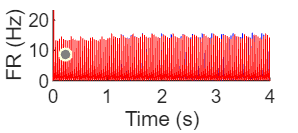

pop = 1;
figure();

hold on;

% plot(timeax(1:100000),squeeze(r(pop,1:100000,4)),'r','LineWidth',0.5);
% plot(timeax(1:100000),squeeze(r(pop,1:100000,5)),'b','LineWidth',0.5);
% plot(timeax(100001:400000),squeeze(r(pop,100001:400000,5)),'b','LineWidth',0.5);
% plot(timeax(100001:400000),squeeze(r(pop,100001:400000,4)),'r','LineWidth',0.5);

plot(timeax,squeeze(r(pop,:,5)),'b','LineWidth',0.3);
plot(timeax,squeeze(r(pop,:,4)),'r','LineWidth',0.3);

hold off;
% axis([stimIn/1000 (time-1000)/1000 11.87 11.89]);
xlabel("Time (s)");
ylabel("FR (Hz)");
xticks([0 1 2 3 4]);

x0 = 0; y0 = 0; width = 4.5; height = 2;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);

% filename = append(filepath,'tc_tri_L23E');
% print(filename, '-dpng', '-r600');
% print(filename, '-dsvg', '-r600');

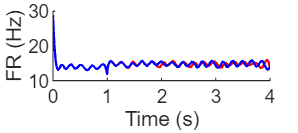

figure();

hold on;

envMthd = 'peak';
envWdo = 4000;
[cond4BF, ] = envelope(squeeze(r(pop,1:step_stimIn,4)),envWdo,envMthd);
[cond5BF, ] = envelope(squeeze(r(pop,1:step_stimIn,5)),envWdo,envMthd);

[cond4AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,4)),envWdo,envMthd);
[cond5AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,5)),envWdo,envMthd);

cond4 = cat(2, cond4BF, cond4AF);
cond5 = cat(2, cond5BF, cond5AF);

plot(timeax,cond4,'r','LineWidth',1);
plot(timeax,cond5,'b','LineWidth',1);

hold off;
% axis([stimIn/1000 (time-1000)/1000 11.87 11.89]);
xlabel("Time (s)");
ylabel("FR (Hz)");
xticks([0 1 2 3 4]);

x0 = 0; y0 = 0; width = 4.5; height = 2;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);

% filename = append(filepath,'tc_tri_L23E_env');
% print(filename, '-dpng', '-r600');
% print(filename, '-dsvg', '-r600');

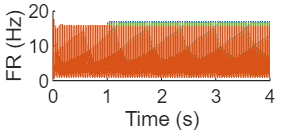

pop = 5;
figure();

hold on;

plot(timeax,squeeze(r(pop,:,4)),'Color','#7E2F8E','LineWidth',0.5);
plot(timeax,squeeze(r(pop,:,1)),'Color','#0072BD','LineWidth',0.5);
plot(timeax,squeeze(r(pop,:,3)),'Color','#EDB120','LineWidth',0.5);
plot(timeax,squeeze(r(pop,:,5)),'Color','#77AC30','LineWidth',0.5);
plot(timeax,squeeze(r(pop,:,2)),'Color','#D95319','LineWidth',0.5);

hold off;
% axis([stimIn/1000 (time-1000)/1000 35 39]);
xlabel("Time (s)");
ylabel("FR (Hz)");
xticks([0 1 2 3 4]);

x0 = 0; y0 = 0; width = 4.5; height = 2;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);

% filename = append(filepath,'tc_tri_L5E');
% print(filename, '-dpng', '-r600');
% print(filename, '-dsvg', '-r600');

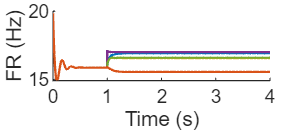

figure();

hold on;

envMthd = 'peak';
envWdo = 4000;
[cond1BF, ] = envelope(squeeze(r(pop,1:step_stimIn,1)),envWdo,envMthd);
[cond2BF, ] = envelope(squeeze(r(pop,1:step_stimIn,2)),envWdo,envMthd);
[cond3BF, ] = envelope(squeeze(r(pop,1:step_stimIn,3)),envWdo,envMthd);
[cond4BF, ] = envelope(squeeze(r(pop,1:step_stimIn,4)),envWdo,envMthd);
[cond5BF, ] = envelope(squeeze(r(pop,1:step_stimIn,5)),envWdo,envMthd);

[cond1AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,1)),envWdo,envMthd);
[cond2AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,2)),envWdo,envMthd);
[cond3AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,3)),envWdo,envMthd);
[cond4AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,4)),envWdo,envMthd);
[cond5AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,5)),envWdo,envMthd);

cond1 = cat(2, cond1BF, cond1AF);
cond2 = cat(2, cond2BF, cond2AF);
cond3 = cat(2, cond3BF, cond3AF);
cond4 = cat(2, cond4BF, cond4AF);
cond5 = cat(2, cond5BF, cond5AF);

plot(timeax,cond1,'Color','#0072BD','LineWidth',1);
plot(timeax,cond3,'Color','#EDB120','LineWidth',1);
plot(timeax,cond4,'Color','#7E2F8E','LineWidth',1);
plot(timeax,cond5,'Color','#77AC30','LineWidth',1);
plot(timeax,cond2,'Color','#D95319','LineWidth',1);

hold off;
% axis([stimIn/1000 (time-1000)/1000 35 39]);
xlabel("Time (s)");
ylabel("FR (Hz)");
xticks([0 1 2 3 4]);

x0 = 0; y0 = 0; width = 4.5; height = 2;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);

% filename = append(filepath,'tc_tri_L5E_env');
% print(filename, '-dpng', '-r600');
% print(filename, '-dsvg', '-r600');

## Plus sign

time = 9000;
stimIn = 5000;
dt = 0.01;
timeax = 0:dt:time;
timeax = timeax'/1000;

stimDur = time - stimIn;
step_stimIn = stimIn/dt;
step_stim = stimDur/dt;

Iattn = 0.02;

Delta_E = 0.115;% 0.075;
Delta_I = 0.03;% 0.03;
ratio_sens_attn = 3;

[r,~,~] = reduce_L4(Delta_E, Delta_I, Iattn, ratio_sens_attn, time, stimIn);
r = r*1000;

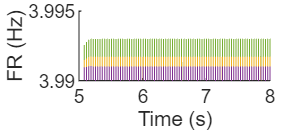

pop = 1;
figure();

hold on;
 
% recX = [1 4 4 1];
% recY = [0 0 200 200];
% r1 = fill(recX, recY, 0.9*[209 211 212]/256,'LineStyle','none');
% alpha(r1,0.5);

% plot(timeax,squeeze(r(pop,:,5)),'b','LineWidth',0.3);
% plot(timeax,squeeze(r(pop,:,4)),'r','LineWidth',0.3);

plot(timeax,squeeze(r(pop,:,5)),'Color','#77AC30','LineWidth',0.3);
plot(timeax,squeeze(r(pop,:,3)),'Color','#EDB120','LineWidth',0.3);
plot(timeax,squeeze(r(pop,:,4)),'Color','#7E2F8E','LineWidth',0.3);

hold off;
axis([stimIn/1000 (time-1000)/1000 3.99 3.995]);
xlabel("Time (s)");
ylabel("FR (Hz)");
xticks([5 6 7 8]);
yticks([3.99 3.995]);

x0 = 0; y0 = 0; width = 4.5; height = 2;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
filename = append(filepath,'tc_plus_L23E');
print(filename, '-dpng', '-r600');
print(filename, '-dsvg', '-r600');

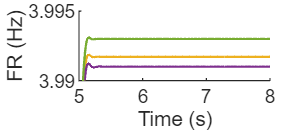

figure();

hold on;

% recX = [1 4 4 1];
% recY = [0 0 200 200];
% r1 = fill(recX, recY, 0.9*[209 211 212]/256,'LineStyle','none');
% alpha(r1,0.5);

envMthd = 'peak';
envWdo = 4000;
% [cond4BF, ] = envelope(squeeze(r(pop,1:step_stimIn,4)),envWdo,envMthd);
% [cond5BF, ] = envelope(squeeze(r(pop,1:step_stimIn,5)),envWdo,envMthd);
% 
% [cond4AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,4)),envWdo,envMthd);
% [cond5AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,5)),envWdo,envMthd);
% 
% cond4 = cat(2, cond4BF, cond4AF);
% cond5 = cat(2, cond5BF, cond5AF);
% 
% plot(timeax,cond4,'r','LineWidth',1);
% plot(timeax,cond5,'b','LineWidth',1);

[cond1BF, ] = envelope(squeeze(r(pop,1:step_stimIn,1)),envWdo,envMthd);
[cond2BF, ] = envelope(squeeze(r(pop,1:step_stimIn,2)),envWdo,envMthd);
[cond3BF, ] = envelope(squeeze(r(pop,1:step_stimIn,3)),envWdo,envMthd);
[cond4BF, ] = envelope(squeeze(r(pop,1:step_stimIn,4)),envWdo,envMthd);
[cond5BF, ] = envelope(squeeze(r(pop,1:step_stimIn,5)),envWdo,envMthd);

[cond1AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,1)),envWdo,envMthd);
[cond2AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,2)),envWdo,envMthd);
[cond3AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,3)),envWdo,envMthd);
[cond4AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,4)),envWdo,envMthd);
[cond5AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,5)),envWdo,envMthd);

cond1 = cat(2, cond1BF, cond1AF);
cond2 = cat(2, cond2BF, cond2AF);
cond3 = cat(2, cond3BF, cond3AF);
cond4 = cat(2, cond4BF, cond4AF);
cond5 = cat(2, cond5BF, cond5AF);

% plot(timeax,cond1,'Color','#0072BD','LineWidth',1);
plot(timeax,cond3,'Color','#EDB120','LineWidth',1);
plot(timeax,cond4,'Color','#7E2F8E','LineWidth',1);
plot(timeax,cond5,'Color','#77AC30','LineWidth',1);
% plot(timeax,cond2,'Color','#D95319','LineWidth',1);

hold off;
axis([stimIn/1000 (time-1000)/1000 3.99 3.995]);
xlabel("Time (s)");
ylabel("FR (Hz)");
xticks([5 6 7 8]);
yticks([3.99 3.995]);

x0 = 0; y0 = 0; width = 4.5; height = 2;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
filename = append(filepath,'tc_plus_L23E_env');
print(filename, '-dpng', '-r600');
print(filename, '-dsvg', '-r600');

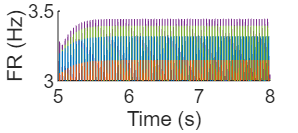

pop = 5;
figure();

hold on;
 
% recX = [1 4 4 1];
% recY = [0 0 200 200];
% r1 = fill(recX, recY, 0.9*[209 211 212]/256,'LineStyle','none');
% alpha(r1,0.5);


plot(timeax,squeeze(r(pop,:,4)),'Color','#7E2F8E','LineWidth',0.3);
plot(timeax,squeeze(r(pop,:,3)),'Color','#EDB120','LineWidth',0.3);
plot(timeax,squeeze(r(pop,:,5)),'Color','#77AC30','LineWidth',0.3);
plot(timeax,squeeze(r(pop,:,1)),'Color','#0072BD','LineWidth',0.3);
plot(timeax,squeeze(r(pop,:,2)),'Color','#D95319','LineWidth',0.3);

hold off;
axis([stimIn/1000 (time-1000)/1000 3 3.5]);
xlabel("Time (s)");
ylabel("FR (Hz)");
xticks([5 6 7 8]);

x0 = 0; y0 = 0; width = 4.5; height = 2;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
filename = append(filepath,'tc_plus_L5E');
print(filename, '-dpng', '-r600');
print(filename, '-dsvg', '-r600');

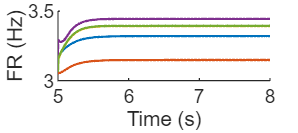

figure();

hold on;

% recX = [1 4 4 1];
% recY = [0 0 200 200];
% r1 = fill(recX, recY, 0.9*[209 211 212]/256,'LineStyle','none');
% alpha(r1,0.5);

envMthd = 'peak';
envWdo = 4000;
[cond1BF, ] = envelope(squeeze(r(pop,1:step_stimIn,1)),envWdo,envMthd);
[cond2BF, ] = envelope(squeeze(r(pop,1:step_stimIn,2)),envWdo,envMthd);
[cond3BF, ] = envelope(squeeze(r(pop,1:step_stimIn,3)),envWdo,envMthd);
[cond4BF, ] = envelope(squeeze(r(pop,1:step_stimIn,4)),envWdo,envMthd);
[cond5BF, ] = envelope(squeeze(r(pop,1:step_stimIn,5)),envWdo,envMthd);

[cond1AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,1)),envWdo,envMthd);
[cond2AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,2)),envWdo,envMthd);
[cond3AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,3)),envWdo,envMthd);
[cond4AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,4)),envWdo,envMthd);
[cond5AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,5)),envWdo,envMthd);

cond1 = cat(2, cond1BF, cond1AF);
cond2 = cat(2, cond2BF, cond2AF);
cond3 = cat(2, cond3BF, cond3AF);
cond4 = cat(2, cond4BF, cond4AF);
cond5 = cat(2, cond5BF, cond5AF);

plot(timeax,cond1,'Color','#0072BD','LineWidth',1);
plot(timeax,cond3,'Color','#EDB120','LineWidth',1);
plot(timeax,cond4,'Color','#7E2F8E','LineWidth',1);
plot(timeax,cond5,'Color','#77AC30','LineWidth',1);
plot(timeax,cond2,'Color','#D95319','LineWidth',1);

hold off;
axis([stimIn/1000 (time-1000)/1000 3 3.5]);
xlabel("Time (s)");
ylabel("FR (Hz)");
xticks([5 6 7 8]);

x0 = 0; y0 = 0; width = 4.5; height = 2;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
filename = append(filepath,'tc_plus_L5E_env');
print(filename, '-dpng', '-r600');
print(filename, '-dsvg', '-r600');

## Square sign

time = 9000;
stimIn = 5000;

dt = 0.01;
timeax = 0:dt:time;
timeax = timeax'/1000;
stimDur = time - stimIn;
step_stimIn = stimIn/dt;
step_stim = stimDur/dt;

Iattn = 0.02;

Delta_E = 0.4;% 0.455;
Delta_I = 0.03;% 0.046;
ratio_sens_attn = 3;

[r,~,~] = reduce_L4(Delta_E, Delta_I, Iattn, ratio_sens_attn, time, stimIn);
r = r*1000;

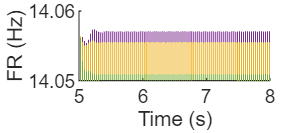

pop = 1;
figure();

hold on;
 
% recX = [1 4 4 1];
% recY = [0 0 200 200];
% r1 = fill(recX, recY, 0.9*[209 211 212]/256,'LineStyle','none');
% alpha(r1,0.5);

% plot(timeax,squeeze(r(pop,:,4)),'r','LineWidth',0.3);
% plot(timeax,squeeze(r(pop,:,5)),'b','LineWidth',0.3);

plot(timeax,squeeze(r(pop,:,4)),'Color','#7E2F8E','LineWidth',0.3);
plot(timeax,squeeze(r(pop,:,3)),'Color','#EDB120','LineWidth',0.3);
plot(timeax,squeeze(r(pop,:,5)),'Color','#77AC30','LineWidth',0.3);

hold off;
axis([stimIn/1000 (time-1000)/1000 14.05 14.06]);
xlabel("Time (s)");
ylabel("FR (Hz)");
xticks([5 6 7 8]);
yticks([14.05 14.06]);

x0 = 0; y0 = 0; width = 4.5; height = 2;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
filename = append(filepath,'tc_sq_L23E');
print(filename, '-dpng', '-r600');
print(filename, '-dsvg', '-r600');

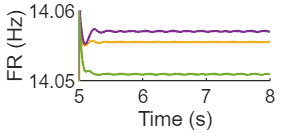

figure();

hold on;

% recX = [1 4 4 1];
% recY = [0 0 200 200];
% r1 = fill(recX, recY, 0.9*[209 211 212]/256,'LineStyle','none');
% alpha(r1,0.5);

envMthd = 'peak';
envWdo = 4000;
% [cond4BF, ] = envelope(squeeze(r(pop,1:step_stimIn,4)),envWdo,envMthd);
% [cond5BF, ] = envelope(squeeze(r(pop,1:step_stimIn,5)),envWdo,envMthd);
% 
% [cond4AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,4)),envWdo,envMthd);
% [cond5AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,5)),envWdo,envMthd);
% 
% cond4 = cat(2, cond4BF, cond4AF);
% cond5 = cat(2, cond5BF, cond5AF);
% 
% plot(timeax,cond4,'r','LineWidth',1);
% plot(timeax,cond5,'b','LineWidth',1);

[cond1BF, ] = envelope(squeeze(r(pop,1:step_stimIn,1)),envWdo,envMthd);
[cond2BF, ] = envelope(squeeze(r(pop,1:step_stimIn,2)),envWdo,envMthd);
[cond3BF, ] = envelope(squeeze(r(pop,1:step_stimIn,3)),envWdo,envMthd);
[cond4BF, ] = envelope(squeeze(r(pop,1:step_stimIn,4)),envWdo,envMthd);
[cond5BF, ] = envelope(squeeze(r(pop,1:step_stimIn,5)),envWdo,envMthd);

[cond1AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,1)),envWdo,envMthd);
[cond2AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,2)),envWdo,envMthd);
[cond3AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,3)),envWdo,envMthd);
[cond4AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,4)),envWdo,envMthd);
[cond5AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,5)),envWdo,envMthd);

cond1 = cat(2, cond1BF, cond1AF);
cond2 = cat(2, cond2BF, cond2AF);
cond3 = cat(2, cond3BF, cond3AF);
cond4 = cat(2, cond4BF, cond4AF);
cond5 = cat(2, cond5BF, cond5AF);

% plot(timeax,cond1,'Color','#0072BD','LineWidth',1);
plot(timeax,cond3,'Color','#EDB120','LineWidth',1);
plot(timeax,cond4,'Color','#7E2F8E','LineWidth',1);
plot(timeax,cond5,'Color','#77AC30','LineWidth',1);
% plot(timeax,cond2,'Color','#D95319','LineWidth',1);

hold off;
axis([stimIn/1000 (time-1000)/1000 14.05 14.06]);
xlabel("Time (s)");
ylabel("FR (Hz)");
xticks([5 6 7 8]);
yticks([14.05 14.06]);

x0 = 0; y0 = 0; width = 4.5; height = 2;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
filename = append(filepath,'tc_sq_L23E_env');
print(filename, '-dpng', '-r600');
print(filename, '-dsvg', '-r600');

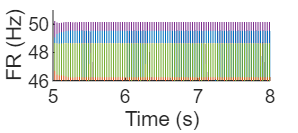

pop = 5;
figure();

hold on;
 
% recX = [1 4 4 1];
% recY = [0 0 200 200];
% r1 = fill(recX, recY, 0.9*[209 211 212]/256,'LineStyle','none');
% alpha(r1,0.5);

plot(timeax,squeeze(r(pop,:,4)),'Color','#7E2F8E','LineWidth',0.3);
plot(timeax,squeeze(r(pop,:,1)),'Color','#0072BD','LineWidth',0.3);
plot(timeax,squeeze(r(pop,:,3)),'Color','#EDB120','LineWidth',0.3);
plot(timeax,squeeze(r(pop,:,5)),'Color','#77AC30','LineWidth',0.3);
plot(timeax,squeeze(r(pop,:,2)),'Color','#D95319','LineWidth',0.3);

hold off;
axis([stimIn/1000 (time-1000)/1000 46 51]);
xlabel("Time (s)");
ylabel("FR (Hz)");
xticks([5 6 7 8]);

x0 = 0; y0 = 0; width = 4.5; height = 2;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
filename = append(filepath,'tc_sq_L5E');
print(filename, '-dpng', '-r600');
print(filename, '-dsvg', '-r600');

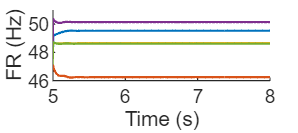

figure();

hold on;

% recX = [1 4 4 1];
% recY = [0 0 200 200];
% r1 = fill(recX, recY, 0.9*[209 211 212]/256,'LineStyle','none');
% alpha(r1,0.5);

envMthd = 'peak';
envWdo = 4000;
[cond1BF, ] = envelope(squeeze(r(pop,1:step_stimIn,1)),envWdo,envMthd);
[cond2BF, ] = envelope(squeeze(r(pop,1:step_stimIn,2)),envWdo,envMthd);
[cond3BF, ] = envelope(squeeze(r(pop,1:step_stimIn,3)),envWdo,envMthd);
[cond4BF, ] = envelope(squeeze(r(pop,1:step_stimIn,4)),envWdo,envMthd);
[cond5BF, ] = envelope(squeeze(r(pop,1:step_stimIn,5)),envWdo,envMthd);

[cond1AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,1)),envWdo,envMthd);
[cond2AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,2)),envWdo,envMthd);
[cond3AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,3)),envWdo,envMthd);
[cond4AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,4)),envWdo,envMthd);
[cond5AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,5)),envWdo,envMthd);

cond1 = cat(2, cond1BF, cond1AF);
cond2 = cat(2, cond2BF, cond2AF);
cond3 = cat(2, cond3BF, cond3AF);
cond4 = cat(2, cond4BF, cond4AF);
cond5 = cat(2, cond5BF, cond5AF);

plot(timeax,cond1,'Color','#0072BD','LineWidth',1);
plot(timeax,cond3,'Color','#EDB120','LineWidth',1);
plot(timeax,cond4,'Color','#7E2F8E','LineWidth',1);
plot(timeax,cond5,'Color','#77AC30','LineWidth',1);
plot(timeax,cond2,'Color','#D95319','LineWidth',1);

hold off;
axis([stimIn/1000 (time-1000)/1000 46 51]);
xlabel("Time (s)");
ylabel("FR (Hz)");
xticks([5 6 7 8]);

x0 = 0; y0 = 0; width = 4.5; height = 2;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
filename = append(filepath,'tc_sq_L5E_env');
print(filename, '-dpng', '-r600');
print(filename, '-dsvg', '-r600');

## Triangle sign

time = 9000;
stimIn = 5000;
dt = 0.01;
timeax = 0:dt:time;
timeax = timeax'/1000;
stimDur = time - stimIn;
step_stimIn = stimIn/dt;
step_stim = stimDur/dt;

Iattn = 0.02;

Delta_E = 0.4;% 0.455;
Delta_I = 0.042;% 0.046;
ratio_sens_attn = 3;

[r,~,~] = reduce_L4(Delta_E, Delta_I, Iattn, ratio_sens_attn, time, stimIn);
r = r*1000;

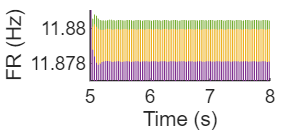

pop = 1;
figure();

hold on;
 
% recX = [1 4 4 1];
% recY = [0 0 200 200];
% r1 = fill(recX, recY, 0.9*[209 211 212]/256,'LineStyle','none');
% alpha(r1,0.5);

% plot(timeax,squeeze(r(pop,:,5)),'b','LineWidth',0.3);
% plot(timeax,squeeze(r(pop,:,4)),'r','LineWidth',0.3);

plot(timeax,squeeze(r(pop,:,5)),'Color','#77AC30','LineWidth',0.3);
plot(timeax,squeeze(r(pop,:,3)),'Color','#EDB120','LineWidth',0.3);
plot(timeax,squeeze(r(pop,:,4)),'Color','#7E2F8E','LineWidth',0.3);

hold off;
axis([stimIn/1000 (time-1000)/1000 11.877 11.881]);
xlabel("Time (s)");
ylabel("FR (Hz)");
xticks([5 6 7 8]);

x0 = 0; y0 = 0; width = 4.5; height = 2;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
filename = append(filepath,'tc_tri_L23E');
print(filename, '-dpng', '-r600');
print(filename, '-dsvg', '-r600');

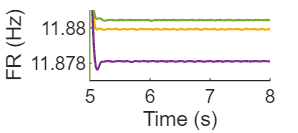

figure();

hold on;

% recX = [1 4 4 1];
% recY = [0 0 200 200];
% r1 = fill(recX, recY, 0.9*[209 211 212]/256,'LineStyle','none');
% alpha(r1,0.5);

envMthd = 'peak';
envWdo = 4000;
% [cond4BF, ] = envelope(squeeze(r(pop,1:step_stimIn,4)),envWdo,envMthd);
% [cond5BF, ] = envelope(squeeze(r(pop,1:step_stimIn,5)),envWdo,envMthd);
% 
% [cond4AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,4)),envWdo,envMthd);
% [cond5AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,5)),envWdo,envMthd);
% 
% cond4 = cat(2, cond4BF, cond4AF);
% cond5 = cat(2, cond5BF, cond5AF);
% 
% plot(timeax,cond4,'r','LineWidth',1);
% plot(timeax,cond5,'b','LineWidth',1);

[cond1BF, ] = envelope(squeeze(r(pop,1:step_stimIn,1)),envWdo,envMthd);
[cond2BF, ] = envelope(squeeze(r(pop,1:step_stimIn,2)),envWdo,envMthd);
[cond3BF, ] = envelope(squeeze(r(pop,1:step_stimIn,3)),envWdo,envMthd);
[cond4BF, ] = envelope(squeeze(r(pop,1:step_stimIn,4)),envWdo,envMthd);
[cond5BF, ] = envelope(squeeze(r(pop,1:step_stimIn,5)),envWdo,envMthd);

[cond1AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,1)),envWdo,envMthd);
[cond2AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,2)),envWdo,envMthd);
[cond3AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,3)),envWdo,envMthd);
[cond4AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,4)),envWdo,envMthd);
[cond5AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,5)),envWdo,envMthd);

cond1 = cat(2, cond1BF, cond1AF);
cond2 = cat(2, cond2BF, cond2AF);
cond3 = cat(2, cond3BF, cond3AF);
cond4 = cat(2, cond4BF, cond4AF);
cond5 = cat(2, cond5BF, cond5AF);

% plot(timeax,cond1,'Color','#0072BD','LineWidth',1);
plot(timeax,cond3,'Color','#EDB120','LineWidth',1);
plot(timeax,cond4,'Color','#7E2F8E','LineWidth',1);
plot(timeax,cond5,'Color','#77AC30','LineWidth',1);
% plot(timeax,cond2,'Color','#D95319','LineWidth',1);

hold off;
axis([stimIn/1000 (time-1000)/1000 11.877 11.881]);
xlabel("Time (s)");
ylabel("FR (Hz)");
xticks([5 6 7 8]);

x0 = 0; y0 = 0; width = 4.5; height = 2;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
filename = append(filepath,'tc_tri_L23E_env');
print(filename, '-dpng', '-r600');
print(filename, '-dsvg', '-r600');

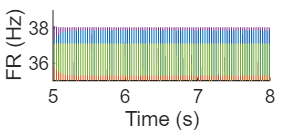

pop = 5;
figure();

hold on;
 
% recX = [1 4 4 1];
% recY = [0 0 200 200];
% r1 = fill(recX, recY, 0.9*[209 211 212]/256,'LineStyle','none');
% alpha(r1,0.5);

plot(timeax,squeeze(r(pop,:,4)),'Color','#7E2F8E','LineWidth',0.3);
plot(timeax,squeeze(r(pop,:,1)),'Color','#0072BD','LineWidth',0.3);
plot(timeax,squeeze(r(pop,:,3)),'Color','#EDB120','LineWidth',0.3);
plot(timeax,squeeze(r(pop,:,5)),'Color','#77AC30','LineWidth',0.3);
plot(timeax,squeeze(r(pop,:,2)),'Color','#D95319','LineWidth',0.3);

hold off;
axis([stimIn/1000 (time-1000)/1000 35 39]);
xlabel("Time (s)");
ylabel("FR (Hz)");
xticks([5 6 7 8]);

x0 = 0; y0 = 0; width = 4.5; height = 2;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
filename = append(filepath,'tc_tri_L5E');
print(filename, '-dpng', '-r600');
print(filename, '-dsvg', '-r600');

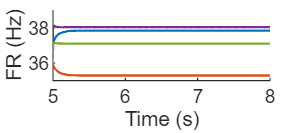

figure();

hold on;

% recX = [1 4 4 1];
% recY = [0 0 200 200];
% r1 = fill(recX, recY, 0.9*[209 211 212]/256,'LineStyle','none');
% alpha(r1,0.5);

envMthd = 'peak';
envWdo = 4000;
[cond1BF, ] = envelope(squeeze(r(pop,1:step_stimIn,1)),envWdo,envMthd);
[cond2BF, ] = envelope(squeeze(r(pop,1:step_stimIn,2)),envWdo,envMthd);
[cond3BF, ] = envelope(squeeze(r(pop,1:step_stimIn,3)),envWdo,envMthd);
[cond4BF, ] = envelope(squeeze(r(pop,1:step_stimIn,4)),envWdo,envMthd);
[cond5BF, ] = envelope(squeeze(r(pop,1:step_stimIn,5)),envWdo,envMthd);

[cond1AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,1)),envWdo,envMthd);
[cond2AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,2)),envWdo,envMthd);
[cond3AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,3)),envWdo,envMthd);
[cond4AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,4)),envWdo,envMthd);
[cond5AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,5)),envWdo,envMthd);

cond1 = cat(2, cond1BF, cond1AF);
cond2 = cat(2, cond2BF, cond2AF);
cond3 = cat(2, cond3BF, cond3AF);
cond4 = cat(2, cond4BF, cond4AF);
cond5 = cat(2, cond5BF, cond5AF);

plot(timeax,cond1,'Color','#0072BD','LineWidth',1);
plot(timeax,cond3,'Color','#EDB120','LineWidth',1);
plot(timeax,cond4,'Color','#7E2F8E','LineWidth',1);
plot(timeax,cond5,'Color','#77AC30','LineWidth',1);
plot(timeax,cond2,'Color','#D95319','LineWidth',1);

hold off;
axis([stimIn/1000 (time-1000)/1000 35 39]);
xlabel("Time (s)");
ylabel("FR (Hz)");
xticks([5 6 7 8]);

x0 = 0; y0 = 0; width = 4.5; height = 2;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
filename = append(filepath,'tc_tri_L5E_env');
print(filename, '-dpng', '-r600');
print(filename, '-dsvg', '-r600');